% PARAMETRI
clear all;
close all;
java.lang.System.gc

frame_intervals = 20;
% Directory principale
main_folder ='C:\Users\39347\OneDrive - Fondazione Istituto Italiano Tecnologia\ARTICOLI\METHODS\sample_1\tracking\data_analysis'; %..\analisiCLuster divisi %cntrl_DARK

% --- Definizione dei flash: intervalli [inizio_frame, fine_frame] ---
flash_intervals_frames = [
   100, 100;
    % aggiungi altri intervalli se necessario
];

% Trova le cartelle "ziapin_*ugml"
ziapin_folders = dir(fullfile(main_folder, 'data*'));
ziapin_folders = ziapin_folders([ziapin_folders.isdir]); % solo directory
for i = 1:length(ziapin_folders)
    ziapin_path = fullfile(main_folder, ziapin_folders(i).name);

    % Trova le sottocartelle "video*"
    video_folders = dir(fullfile(ziapin_path, 'Collective_splitting*'));
    video_folders = video_folders([video_folders.isdir]); % solo directory

    for j = 1:length(video_folders)
        video_path = fullfile(ziapin_path, video_folders(j).name);

            % --- PULIZIA MEMORIA AD OGNI ITERAZIONE ---
    close all;                    % chiude tutte le figure precedenti
    clearvars -except main_folder frame_intervals flash_intervals_frames ...
                      ziapin_folders ziapin_path video_folders video_path j i;
    % resetta le variabili che crescono per concatenazione
    msd_curve_all = [];
    boxplot_data  = [];
    % -----------------------------------------
               
% Cerca file che termina con _save
file_struct = dir(fullfile(video_path, '*round_data.mat')); % qualsiasi estensione
%file_struct = dir(fullfile(video_path, 'Untitledsave.xml'));

if ~isempty(file_struct)
    file_name = file_struct.name; % Prende il primo che trova (se ce ne sono più)
    file_path = fullfile(video_path, file_struct(1).name);
    msd_path = fullfile(video_path, 'MSD_circling');
if ~exist(msd_path, 'dir')
    mkdir(msd_path);   % crea la cartella se non esiste
end


% CARICAMENTO DATI
dataStruct = load(file_path);
converted_data = dataStruct.round_data;
max_frames = max(converted_data.FRAME_SOURCE);
num_intervals = floor(max_frames / frame_intervals);

% PREALLOC
msd_evolutions = cell(1, num_intervals);
msd_std_evolutions = cell(1, num_intervals);
msd_mean_per_interval = NaN(1, num_intervals);
msd_std_per_interval = NaN(1, num_intervals);
msd_per_alga_all = cell(1, num_intervals);

% CICLO SU OGNI INTERVALLO
for interval_index = 1:num_intervals
    % Definizione intervallo
    start_frame = (interval_index - 1) * frame_intervals + 1;
    end_frame = start_frame + frame_intervals - 1;
    interval_frames = start_frame:end_frame;

    % Raggruppa i dati per TRACK_ID e conta il numero di frame
    algae_in_interval = converted_data(ismember(converted_data.FRAME_SOURCE, interval_frames), :);
    [track_ids, ~, group_indices] = unique(algae_in_interval.TRACK_ID);
    frame_counts = accumarray(group_indices, 1);

    % Trova le tracce valide (con esattamente frame_intervals frame)
    valid_tracks = track_ids(frame_counts == frame_intervals);

    % Seleziona solo le traiettorie valide
    algae_in_interval = algae_in_interval(ismember(algae_in_interval.TRACK_ID, valid_tracks), :);

    % Debug: Quante tracce valide
    fprintf('Intervallo %d: %d tracce valide\n', interval_index, length(valid_tracks));
    if isempty(valid_tracks)
        continue;
    end

    % --- Calcolo dei tempi in secondi per ogni intervallo ---
flash_intervals_times = nan(size(flash_intervals_frames));
for ff = 1:size(flash_intervals_frames,1)
    idx_start = find(converted_data.FRAME_SOURCE == flash_intervals_frames(ff,1), 1, 'first');
    idx_end   = find(converted_data.FRAME_SOURCE == flash_intervals_frames(ff,2), 1, 'first');
    if ~isempty(idx_start)
        flash_intervals_times(ff,1) = converted_data.POSITION_T_SOURCE(idx_start);
    end
    if ~isempty(idx_end)
        flash_intervals_times(ff,2) = converted_data.POSITION_T_SOURCE(idx_end);
    end
end

 % Calcolo dell'MSD per ogni alga
unique_tracks = unique(algae_in_interval.TRACK_ID);
msd_per_alga = NaN(length(unique_tracks), frame_intervals);

for i = 1:length(unique_tracks)
    track_id = unique_tracks(i);
    track_data = algae_in_interval(algae_in_interval.TRACK_ID == track_id, :);
    track_data = sortrows(track_data, 'FRAME_SOURCE');
    x0 = track_data.POSITION_X_SOURCE(1);
    y0 = track_data.POSITION_Y_SOURCE(1);
    msd_per_alga(i,:) = (track_data.POSITION_X_SOURCE - x0).^2 + (track_data.POSITION_Y_SOURCE - y0).^2;
end

msd_per_alga_all{interval_index} = msd_per_alga; % <-- METTILA QUI!


    % Calcolo statistico
    msd_mean_per_frame = mean(msd_per_alga, 1, 'omitnan');
    msd_std_per_frame = std(msd_per_alga, 0, 1, 'omitnan');
    msd_se_per_frame = msd_std_per_frame ./ sqrt(sum(~isnan(msd_per_alga), 1));

    % Salvataggio risultati intermedi
    msd_evolutions{interval_index} = msd_mean_per_frame;
    msd_std_evolutions{interval_index} = msd_std_per_frame;
    msd_mean_per_interval(interval_index) = mean(msd_mean_per_frame, 'omitnan');
    msd_std_per_interval(interval_index) = std(msd_mean_per_frame, 'omitnan');

    % SALVA CSV PER INTERVALLO (stesso formato del tuo originale)
    % Prepara i dati per la tabella assicurandosi che abbiano la stessa lunghezza
    frames = (1:frame_intervals)';
    msd_mean = msd_mean_per_frame';
    msd_std = msd_std_per_frame';
    msd_se = msd_se_per_frame';
    
    % Verifica che tutte le colonne abbiano la stessa lunghezza
    if length(frames) == length(msd_mean) && length(msd_mean) == length(msd_std) && length(msd_std) == length(msd_se)
        % Salva i risultati in una tabella per l'intervallo corrente
        interval_table = table(frames, msd_mean, msd_std, msd_se, ...
            'VariableNames', {'Frame', 'MSD_Mean', 'MSD_Std', 'MSD_SE'});
        file_name = 'msd_evolution_intervals.xlsx';  % Unico file excel
        sheet_name = sprintf('Interval_%d', interval_index);  % nome foglio
        writetable(interval_table, fullfile(msd_path, file_name), 'Sheet', sheet_name);
    else
        warning('Le colonne hanno lunghezze diverse per l''intervallo %d', interval_index);
    end
end

Intervallo 1: 34 tracce valide
Intervallo 2: 38 tracce valide
Intervallo 3: 47 tracce valide
Intervallo 4: 52 tracce valide
Intervallo 5: 54 tracce valide
Intervallo 6: 62 tracce valide
Intervallo 7: 67 tracce valide
Intervallo 8: 71 tracce valide
Intervallo 9: 73 tracce valide
Intervallo 10: 71 tracce valide
Intervallo 11: 68 tracce valide
Intervallo 12: 70 tracce valide
Intervallo 13: 69 tracce valide
Intervallo 14: 69 tracce valide
Intervallo 15: 73 tracce valide
Intervallo 16: 70 tracce valide
Intervallo 17: 72 tracce valide
Intervallo 18: 71 tracce valide
Intervallo 19: 68 tracce valide
Intervallo 20: 74 tracce valide
Intervallo 21: 77 tracce valide
Intervallo 22: 75 tracce valide
Intervallo 23: 72 tracce valide
Intervallo 24: 69 tracce valide
Intervallo 25: 64 tracce valide
Intervallo 26: 61 tracce valide
Intervallo 27: 53 tracce valide
Intervallo 28: 50 tracce valide
Intervallo 29: 42 tracce valide


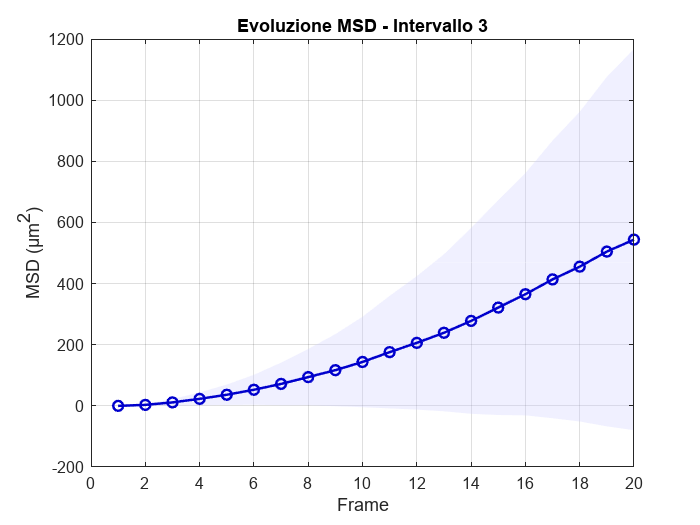

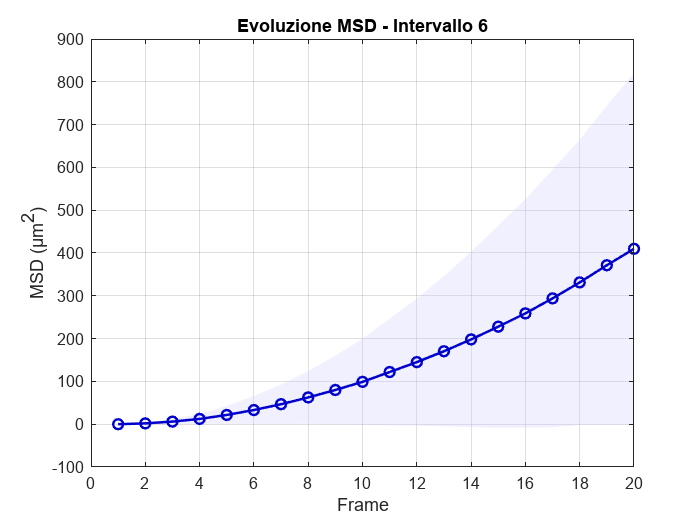

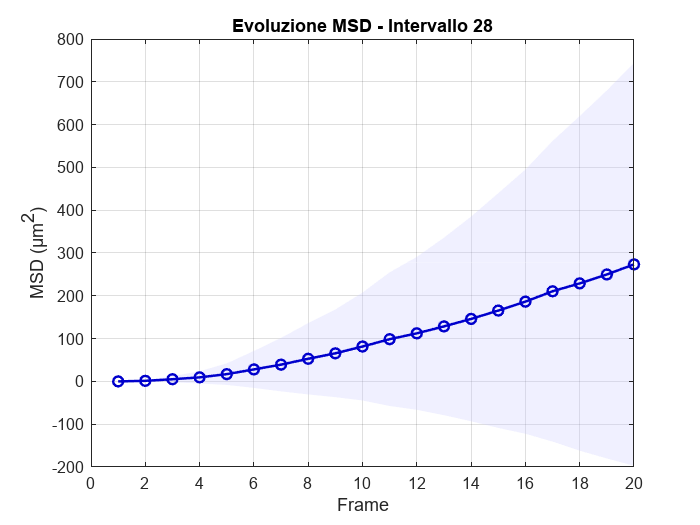



% TABELLA AGGREGATA FINALE
intervals = (1:num_intervals)';
Tfinal = table(intervals, msd_mean_per_interval', msd_std_per_interval', ...
    'VariableNames', {'Interval', 'MSD_Mean', 'MSD_Std'});
% writetable(Tfinal, 'msd_mean_per_interval_with_error.xlsx');

% === AGGIUNGI QUESTO BLOCCO PER L'ASSE DEL TEMPO ===
% Calcola il tempo (in secondi) associato a ciascun intervallo
interval_times_s = zeros(num_intervals, 1);
for k = 1:num_intervals
    start_frame = (k - 1) * frame_intervals + 1;
    idx = find(converted_data.FRAME_SOURCE == start_frame, 1, 'first');
    if ~isempty(idx)
        interval_times_s(k) = converted_data.POSITION_T_SOURCE(idx);
    else
        interval_times_s(k) = NaN;
    end
end
% === PLOT MSD MEDIO PER INTERVALLO ===
% === PLOT MSD MEDIO PER INTERVALLO ===
h1 = figure('Name','MSDmean');
fill([intervals', fliplr(intervals')], ...
     [msd_mean_per_interval + msd_std_per_interval, fliplr(msd_mean_per_interval - msd_std_per_interval)], ...
     [0.8 0.8 1], 'EdgeColor', 'none', 'FaceAlpha', 0.3);
hold on;
plot(intervals, msd_mean_per_interval, '-o', 'LineWidth', 1.5, 'MarkerSize', 6, 'Color', [0 0 0.8]);
xlabel('Interval');
ylabel('MSD average (\mum^2)');
title('MSD Average for Interval with error');
grid on;

ax1 = gca;

% --- CREA UN ASSE SUPERIORE PULITO CON I SECONDI ---
% Calcola i tick e le etichette corrispondenti
tick_idx = ax1.XTick;
tick_idx = tick_idx(tick_idx>=1 & tick_idx<=numel(interval_times_s));
sec_labels = strings(size(tick_idx));
for i=1:length(tick_idx)
    val = interval_times_s(round(tick_idx(i)));
    if ~isnan(val)
        sec_labels(i) = sprintf('%.1f', val);
    else
        sec_labels(i) = "";
    end
end

ax1_pos = ax1.Position;
% ax2 = axes('Position', ax1_pos, ...
%            'XAxisLocation','top', ...
%            'YAxisLocation','right', ...
%            'Color','none', ...
%            'XColor','k', ...
%            'YColor','none', ...
%            'Box','off');
% 
% set(ax2, 'XLim', ax1.XLim, ...
%          'XTick', tick_idx, ...
%          'XTickLabel', sec_labels, ...
%          'XLabel', text(0.5,1.07,'Time [s]','Units','normalized','HorizontalAlignment','center','FontWeight','bold','Parent',ax2));
% 
% ax2.XAxis.TickLength = [0 0]; % niente tacche
% linkaxes([ax1 ax2],'x')        % assi collegati

axes(ax1); % torna all'asse principale

% --- DISEGNA I FLASH (come suggerito nella risposta precedente) ---
flash_intervals = ceil(flash_intervals_frames / frame_intervals); % conversione frame → intervallo

draw_flash_areas(flash_intervals);

hold off;
% === PLOT CURVE MSD DI TUTTI GLI INTERVALLI IN SCALA DI COLORE ===
h2=figure('Name','MSDevolution');
hold on;
frames = 1:frame_intervals;
cmap = parula(num_intervals);
for i = 1:num_intervals
    if ~isempty(msd_evolutions{i})
        plot(frames, msd_evolutions{i}, 'LineWidth', 1.5, 'Color', cmap(i,:));
    end
end
colormap(cmap);
cb = colorbar;
cb.Ticks = linspace(0,1,6);
cb.TickLabels = round(linspace(1,num_intervals,6));
cb.Label.String = 'Interval';
xlabel('Frame in Interval');
ylabel('MSD (µm^2)');
title('MSD curves for all intervals (colormap)');
grid on;
hold off;

% === PLOT CURVE MSD NORMALIZZATE DI TUTTI GLI INTERVALLI IN SCALA DI COLORE ===
h3=figure('Name','MSDevolutionNorm');
hold on;
for i = 1:num_intervals
    if ~isempty(msd_evolutions{i}) && max(msd_evolutions{i}) > 0
        norm_curve = msd_evolutions{i}/max(msd_evolutions{i});
        plot(frames, norm_curve, 'LineWidth', 1.2, 'Color', cmap(i,:));
    end
end
colormap(cmap);
cb = colorbar;
cb.Ticks = linspace(0,1,6);
cb.TickLabels = round(linspace(1,num_intervals,6));
cb.Label.String = 'Interval';
xlabel('Frame in Interval');
ylabel('MSD normalized');
title('Normalised MSD curves by interval(colormap)');
grid on;
hold off;

% === PLOT CURVE MSD ED ERRORI PER INTERVALLI SPECIFICI (esempio: 3, 6, 28) ===
for selected_interval = [3, 6, 28]
    if selected_interval <= num_intervals && ~isempty(msd_evolutions{selected_interval})
        msd_curve = msd_evolutions{selected_interval};
        msd_std_curve = msd_std_evolutions{selected_interval};
        frames = 1:length(msd_curve);
        figure;
        fill([frames, fliplr(frames)], ...
             [msd_curve + msd_std_curve, fliplr(msd_curve - msd_std_curve)], ...
             [0.8 0.8 1], 'EdgeColor', 'none', 'FaceAlpha', 0.3);
        hold on;
        plot(frames, msd_curve, '-o', 'LineWidth', 1.5, 'MarkerSize', 6, 'Color', [0 0 0.8]);
        xlabel('Frame');
        ylabel('MSD (µm^2)');
        title(sprintf('Evoluzione MSD - Intervallo %d', selected_interval));
        grid on;
    end
end

% === DEFINIZIONE DEI MODELLI DI FIT ===
msd_global = mean(cell2mat(msd_evolutions'),1,'omitnan');
fit_models = {
    'Linear',              'poly1',     [];
    'Quadratic',           'poly2',     [];
    'Cubic',               'poly3',     [];
    'Exponential',         'a*exp(b*x)', [max(msd_global), 0.05];
    'PowerLaw',           'a*x^b',     [max(msd_global), 1];
    'AnomDiff',         'a*(1-exp(-b*x))', [max(msd_global), 0.05];
     'OrnsteinUhlenbeck',   'L^2*(1 - exp(-x/tau_c))',   [max(msd_global), 1];
};
num_models = size(fit_models,1);

frame_vec = (1:frame_intervals)';

% === FIT SU OGNI INTERVALLO (DATI REALI E NORMALIZZATI SOLO IN Y) ===
fit_results.interval = struct();
fit_results.interval_norm = struct();
for m = 1:num_models
    fit_results.interval.(fit_models{m,1}) = repmat(struct( ...
        'params', nan, ...
        'errs', nan, ...
        'param_names', {{}}, ...
        'r2', nan, ...
        'rmse', nan ...
    ), num_intervals, 1);
    fit_results.interval_norm.(fit_models{m,1}) = repmat(struct( ...
        'params', nan, ...
        'errs', nan, ...
        'param_names', {{}}, ...
        'r2', nan, ...
        'rmse', nan ...
    ), num_intervals, 1);
end

for interval_index = 1:num_intervals
    msd_curve = msd_evolutions{interval_index};
    if isempty(msd_curve) || all(isnan(msd_curve)), continue; end
    x = frame_vec;
    y = msd_curve(:);
    y_norm = y / max(y);

    for m = 1:num_models
        nome = fit_models{m,1};
        modello = fit_models{m,2};
        start = fit_models{m,3};
        % --- FIT DATI REALI ---
        try
            if contains(modello, 'poly')
                [f, gof] = fit(x, y, modello);
            else
                ft = fittype(modello, 'independent', 'x');
                [f, gof] = fit(x, y, ft, 'StartPoint', start);
            end
            ci = confint(f);
            par_names = coeffnames(f);
            coeffvals = cellfun(@(n) f.(n), par_names);
            coefferrs = (ci(2,:) - ci(1,:))/2;
            r2 = gof.rsquare;
            rmse = gof.rmse;
        catch
            par_names = {};
            coeffvals = nan;
            coefferrs = nan;
            r2 = nan;
            rmse = nan;
        end
        fit_results.interval.(nome)(interval_index) = struct(...
            'params', coeffvals, ...
            'errs', coefferrs, ...
            'param_names', {par_names}, ...
            'r2', r2, ...
            'rmse', rmse);

        % --- FIT DATI NORMALIZZATI IN Y (x = frame) ---
        try
            if contains(modello, 'poly')
                [f, gof] = fit(x, y_norm, modello);
            else
                ft = fittype(modello, 'independent', 'x');
                start_norm = [1, 1];
                [f_norm, gof_norm] = fit(x, y_norm, ft, 'StartPoint', start_norm);
                %[f, gof] = fit(x, y_norm, ft, 'StartPoint', start);
            end
            ci = confint(f);
            par_names = coeffnames(f);
            coeffvals = cellfun(@(n) f.(n), par_names);
            coefferrs = (ci(2,:) - ci(1,:))/2;
            r2 = gof.rsquare;
            rmse = gof.rmse;
        catch
            par_names = {};
            coeffvals = nan;
            coefferrs = nan;
            r2 = nan;
            rmse = nan;
        end
        fit_results.interval_norm.(nome)(interval_index) = struct(...
            'params', coeffvals, ...
            'errs', coefferrs, ...
            'param_names', {par_names}, ...
            'r2', r2, ...
            'rmse', rmse);
    end
end

% === FIT SU MSD global (DATI REALI) ===
x = frame_vec;
y = msd_global(:);

fit_results.global = struct();
fit_results.global_norm = struct();

for m = 1:num_models
    nome = fit_models{m,1};
    modello = fit_models{m,2};
    start = fit_models{m,3};
    % --- FIT REALE ---
    try
        if contains(modello, 'poly')
            [f, gof] = fit(x, y, modello);
        else
            ft = fittype(modello, 'independent', 'x');
            [f, gof] = fit(x, y, ft, 'StartPoint', start);
        end
        ci = confint(f);
        par_names = coeffnames(f);
        coeffvals = cellfun(@(n) f.(n), par_names);
        coefferrs = (ci(2,:) - ci(1,:))/2;
        r2 = gof.rsquare;
        rmse = gof.rmse;
    catch
        par_names = {};
        coeffvals = nan;
        coefferrs = nan;
        r2 = nan;
        rmse = nan;
    end
    fit_results.global.(nome) = struct(...
        'params', coeffvals, ...
        'errs', coefferrs, ...
        'param_names', {par_names}, ...
        'r2', r2, ...
        'rmse', rmse);

    % --- FIT global NORMALIZZATO SOLO IN Y ---
    y_norm = y / max(y);
    try
        if contains(modello, 'poly')
            [f, gof] = fit(x, y_norm, modello);
        else
            ft = fittype(modello, 'independent', 'x');
            if strcmp(nome, 'PowerLaw')
                start_norm = [1, 1];
            else
                start_norm = start;
            end
        [f, gof] = fit(x, y_norm, ft, 'StartPoint', start_norm);
        end

        ci = confint(f);
        par_names = coeffnames(f);
        coeffvals = cellfun(@(n) f.(n), par_names);
        coefferrs = (ci(2,:) - ci(1,:))/2;
        r2 = gof.rsquare;
        rmse = gof.rmse;
    catch
        par_names = {};
        coeffvals = nan;
        coefferrs = nan;
        r2 = nan;
        rmse = nan;
    end
    fit_results.global_norm.(nome) = struct(...
        'params', coeffvals, ...
        'errs', coefferrs, ...
        'param_names', {par_names}, ...
        'r2', r2, ...
        'rmse', rmse);
end

save(fullfile(msd_path,'fit_results_struct.mat'),'fit_results');


% --- Parametri base
frames = (1:frame_intervals)';
maxPerFig = 7; % Quanti fit per figura (modifica se vuoi più/meno fit per plot)
n_fig = ceil(num_models / maxPerFig);

% --- Funzioni di valutazione fit
eval_models = {
    @(b,x) b(1)*x + b(2);                           % poly1
    @(b,x) b(1)*x.^2 + b(2)*x + b(3);               % poly2
    @(b,x) b(1)*x.^3 + b(2)*x.^2 + b(3)*x + b(4);   % poly3
    @(b,x) b(1)*exp(b(2)*x);                        % Esponenziale
    @(b,x) b(1)*x.^b(2);                            % Powerlaw
    @(b,x) b(1)*(1 - exp(-b(2)*x));                 % DiffAnom
    @(b,x) b(1)^2 * (1 - exp(-x./b(2)));                           % OU
};

model_labels = fit_models(:,1);

% === FIGURA 1: Fit su dati reali ===
for fig = 1:n_fig
    h4=figure('Name', 'DataFit');
    hold on;
    plot(frames, msd_global, 'ko-', 'LineWidth', 2, 'DisplayName', 'MSD mean');
    colors = lines(num_models);
    idx_start = (fig-1)*maxPerFig+1;
    idx_end = min(fig*maxPerFig, num_models);

    % --- Plot fit
    for m = idx_start:idx_end
        dati = fit_results.global.(model_labels{m});
        coeffs = dati.params;
        if all(isnan(coeffs)), continue; end
        yfit = eval_models{m}(coeffs, frames);
        plot(frames, yfit, '--', 'Color', colors(m,:), 'LineWidth', 1.5, ...
            'DisplayName', sprintf('%s (R2=%.3f)', model_labels{m}, dati.r2));
    end
    legend('show');
    xlabel('Frame');
    ylabel('MSD (\mum^2)');
    title(sprintf('Fit global MSD models (raw data)'));
    grid on;
       hold off;
    
end


% === FIGURA 2: Fit su dati normalizzati (solo y) ===
msd_global_norm = msd_global / max(msd_global);
for fig = 1:n_fig
     h41=figure('Name', 'DataFitNorm');
    hold on;
    plot(frames, msd_global_norm, 'ko-', 'LineWidth', 2, 'DisplayName', 'MSD mean norm');
    colors = lines(num_models);
    idx_start = (fig-1)*maxPerFig+1;
    idx_end = min(fig*maxPerFig, num_models);

    % --- Plot fit
    for m = idx_start:idx_end
        dati = fit_results.global_norm.(model_labels{m});
        coeffs = dati.params;
        if all(isnan(coeffs)), continue; end
        yfit = eval_models{m}(coeffs, frames);
        plot(frames, yfit, '--', 'Color', colors(m,:), 'LineWidth', 1.5, ...
            'DisplayName', sprintf('%s (R2=%.3f)', model_labels{m}, dati.r2));
    end
    legend('show');
    xlabel('Frame');
    ylabel('MSD normalized');

    title(sprintf('Fit global MSD models (normalized data)', fig, n_fig));
    grid on;
    hold off;
    
end

% === Stampa parametri a video per MSD global (reale e normalizzato) ===
fprintf('\n=== FIT PARAMETERS ON MSD global ===\n');


=== FIT PARAMETERS ON MSD global ===


for m = 1:num_models
    dati = fit_results.global.(model_labels{m});
    coeffs = dati.params;
    errs = dati.errs;
    par_names = dati.param_names;
    if all(isnan(coeffs)), continue; end
    fprintf('\n%s:\n', model_labels{m});
    for p = 1:length(par_names)
        fprintf('   %s = %.4g ± %.2g\n', par_names{p}, coeffs(p), errs(p));
    end
    fprintf('   R2 = %.4f, RMSE = %.4f\n', dati.r2, dati.rmse);
end

Linear:


   p1 = 22.67 ± 2.2
   p2 = -79.02 ± 27


   R2 = 0.9615, RMSE = 27.5889


Quadratic:


   p1 = 0.8792 ± 0.044
   p2 = 4.211 ± 0.95
   p3 = -11.32 ± 4.3


   R2 = 0.9996, RMSE = 2.7521


Cubic:


   p1 = -0.0164 ± 0.0025
   p2 = 1.396 ± 0.081
   p3 = -0.2355 ± 0.74
   p4 = -2.605 ± 1.8


   R2 = 1.0000, RMSE = 0.7927


Exponential:


   a = 28.06 ± 8
   b = 0.1394 ± 0.016


   R2 = 0.9704, RMSE = 24.1810


PowerLaw:


   a = 1.695 ± 0.15
   b = 1.844 ± 0.032


   R2 = 0.9995, RMSE = 2.9917


AnomDiff:


   a = 5.198e+05 ± 9.1e+08
   b = 3.249e-05 ± 0.057


   R2 = 0.8800, RMSE = 48.6835


OrnsteinUhlenbeck:


   L = 1780 ± 2e+06
   tau_c = 1.875e+05 ± 4.2e+08


   R2 = 0.8801, RMSE = 48.6720



fprintf('\n=== FIT PARAMETERS ON MSD global NORMALIZED ===\n');


=== FIT PARAMETERS ON MSD global NORMALIZED ===


for m = 1:num_models
    dati = fit_results.global_norm.(model_labels{m});
    coeffs = dati.params;
    errs = dati.errs;
    par_names = dati.param_names;
    if all(isnan(coeffs)), continue; end
    fprintf('\n%s (normalized):\n', model_labels{m});
    for p = 1:length(par_names)
        fprintf('   %s = %.4g ± %.2g\n', par_names{p}, coeffs(p), errs(p));
    end
    fprintf('   R2 = %.4f, RMSE = %.4f\n', dati.r2, dati.rmse);
end

Linear (normalized):


   p1 = 0.05391 ± 0.0053
   p2 = -0.1879 ± 0.064


   R2 = 0.9615, RMSE = 0.0656


Quadratic (normalized):


   p1 = 0.002091 ± 0.0001
   p2 = 0.01001 ± 0.0023
   p3 = -0.02691 ± 0.01


   R2 = 0.9996, RMSE = 0.0065


Cubic (normalized):


   p1 = -3.9e-05 ± 6e-06
   p2 = 0.003319 ± 0.00019
   p3 = -0.00056 ± 0.0018
   p4 = -0.006194 ± 0.0044


   R2 = 1.0000, RMSE = 0.0019


Exponential (normalized):


   a = -3.975 ± 3.8e+09
   b = -10.98 ± 9.4e+08


   R2 = -1.4230, RMSE = 0.5202


PowerLaw (normalized):


   a = 2.139e-05 ± 1.1
   b = -4.791 ± 2e+06


   R2 = -1.4230, RMSE = 0.5202


AnomDiff (normalized):


   a = 976.3 ± 1.4e+06
   b = 4.115e-05 ± 0.057


   R2 = 0.8800, RMSE = 0.1158


OrnsteinUhlenbeck (normalized):


   L = 57.19 ± 1.1e+05
   tau_c = 8.143e+04 ± 3.1e+08


   R2 = 0.8801, RMSE = 0.1157


%% === 1. COSTRUISCI param_struct con gestione dei fit falliti ===
param_struct = struct();

for m = 1:num_models
    nome = fit_models{m,1};

    % Numero di parametri del modello
    param_names = fit_results.interval.(nome)(1).param_names;
    npar = numel(param_names);

    % Preallocazione delle matrici
    param_struct.(nome).params = nan(num_intervals, npar);
    param_struct.(nome).errs  = nan(num_intervals, npar);
    param_struct.(nome).r2    = nan(num_intervals, 1);
    param_struct.(nome).rmse  = nan(num_intervals, 1);

    % Loop su intervalli
    for k = 1:num_intervals
        fit_k = fit_results.interval.(nome)(k);

        % Controllo di fitting fallito
        fit_failed = isempty(fit_k.params) || numel(fit_k.params) ~= npar;

        if ~fit_failed
            param_struct.(nome).params(k,:) = fit_k.params(:)';
            param_struct.(nome).errs(k,:)   = fit_k.errs(:)';
            param_struct.(nome).r2(k)       = fit_k.r2;
            param_struct.(nome).rmse(k)     = fit_k.rmse;
        else
            % Lasciamo NaN (già preallocati) → indicano fitting non riuscito
            param_struct.(nome).r2(k)   = NaN;
            param_struct.(nome).rmse(k) = NaN;
        end
    end

    param_struct.(nome).param_names = param_names;
end


% === 2. ESPORTA SU FILE EXCEL (.xlsx consigliato) ===
outfilename = fullfile(msd_path,'fit_parameters_models.xlsx');
for m = 1:num_models
    nome = fit_models{m,1};
    npar = length(param_struct.(nome).param_names);
    par_names = param_struct.(nome).param_names;
    intervalli = (1:num_intervals)';
    % Prepara la tabella
    T = table(intervalli, ...
        param_struct.(nome).r2, ...
        param_struct.(nome).rmse, ...
        'VariableNames', {'Intervallo','R2','RMSE'});
    % Parametri e errori
    for p = 1:npar
        T.(['param_' par_names{p}]) = param_struct.(nome).params(:,p);
        T.(['err_' par_names{p}])   = param_struct.(nome).errs(:,p);
    end
    % Esporta su foglio
    writetable(T, outfilename, 'Sheet', nome(1:min(31,end)));
end

% === 3. CLASSIFICA AUTOMATICA dei modelli migliori (sempre Lineare e Powerlaw + 2 migliori extra) ===
meanR2 = zeros(num_models,1);
for m = 1:num_models
    nome = fit_models{m,1};
    meanR2(m) = nanmean(param_struct.(nome).r2);
end
% Trova indici
idx_lineare = find(strcmp(fit_models(:,1), 'Linear'));
idx_powerlaw = find(strcmp(fit_models(:,1), 'PowerLaw'));
mask = true(num_models,1); mask([idx_lineare, idx_powerlaw]) = false;
[~, idxSort] = sort(meanR2(mask), 'descend');
idx_rest = find(mask);
idx_top = idx_rest(idxSort(1:2)); % Primi 2 migliori esclusi quelli fissi
idx_plot = [idx_lineare; idx_powerlaw; idx_top(:)];
modelli_plot = fit_models(idx_plot,1);

fprintf('\nModelli selezionati automaticamente per il plot:\n');


Modelli selezionati automaticamente per il plot:


disp(modelli_plot);

    {'Linear'   }
    {'PowerLaw' }
    {'Cubic'    }
    {'Quadratic'}




% === 4. PLOT: 4 figure (una per modello), subplot per ogni parametro ===
frames_intervals = (1:num_intervals)';
model_struct_name = @(s) matlab.lang.makeValidName(s); % nomi campo MATLAB validi

for mm = 1:length(idx_plot)
    nome = modelli_plot{mm};
    fieldname = model_struct_name(nome);

    % Ottieni i nomi dei parametri validi (escludi stringhe vuote)
    all_param_names = param_struct.(fieldname).param_names;
    valid_idx = find(~cellfun(@isempty, all_param_names)); % INDICI numerici dei parametri validi
    param_names = all_param_names(valid_idx);
    npar = numel(param_names);

    % Crea una figura per ogni modello
    h51=figure('Name', sprintf('Fit parameters - %s', nome), 'Color', 'w');
    for p = 1:npar
        subplot(npar, 1, p);
        x = frames_intervals;
        y = param_struct.(fieldname).params(:, valid_idx(p)); % <-- ORA usa valid_idx(p), che è un indice numerico!
        e = param_struct.(fieldname).errs(:, valid_idx(p));   % idem per errore
        hold on;
        col = lines(1);

        % Banda di errore
        fill([x; flipud(x)], [y+e; flipud(y-e)], col, ...
            'FaceAlpha', 0.3, 'EdgeColor', 'none');
        % Linea centrale e punti
        plot(x, y, '-', 'Color', col, 'LineWidth', 2);
        plot(x, y, 'o', 'Color', col, 'MarkerFaceColor', col);

        % Banda flash
        flash_intervals = ceil(flash_intervals_frames / frame_intervals); % frame → intervallo
        draw_flash_areas(flash_intervals);

        ylabel(param_names{p}, 'Interpreter', 'none');
        grid on;
        if p == 1
            title(sprintf('Fit parameters - Model: %s', nome), 'FontWeight', 'bold');
        end
        if p == npar
            xlabel('Interval');
        end

        % Etichette tempo [s] sopra il grafico (INTERNO)
        ylimit = ylim;
        ypos = ylimit(2) + 0.06*(ylimit(2)-ylimit(1));
        tick_idx = get(gca,'XTick');
        tick_idx = tick_idx(tick_idx>=1 & tick_idx<=numel(interval_times_s));
        sec_labels = strings(size(tick_idx));
        for i=1:length(tick_idx)
            val = interval_times_s(round(tick_idx(i)));
            if ~isnan(val)
                sec_labels(i) = sprintf('%.1f', val);
            else
                sec_labels(i) = "";
            end
        end
        for i = 1:length(tick_idx)
            if strlength(sec_labels(i)) > 0
                text(tick_idx(i), ypos, sec_labels(i), ...
                    'HorizontalAlignment', 'center', ...
                    'VerticalAlignment', 'bottom', ...
                    'FontWeight', 'bold', ...
                    'Color', [0.1 0.1 0.1], ...
                    'FontSize', 9, ...
                    'Clipping', 'on');
            end
        end
        if p == 1
            text(mean(xlim), ylimit(2) + 0.12*(ylimit(2)-ylimit(1)), 'Time [s]', ...
                'HorizontalAlignment', 'center', ...
                'VerticalAlignment', 'bottom', ...
                'FontWeight', 'bold', ...
                'FontSize', 10, ...
                'Clipping', 'on');
        end
        hold off;
    end
     % === SALVATAGGIO FIG E PNG ===
    savefig(h51, fullfile(msd_path, sprintf('FitParams_%s.fig', nome)));  % formato MATLAB
    exportgraphics(h51, fullfile(msd_path, sprintf('FitParams_%s.png', nome)), 'Resolution', 300); % PNG ad alta risoluzione
end

% === 5. PLOT: R2 per i 4 modelli selezionati (asse scalato) ===
h5=figure('Name', 'R2 dei modelli selezionati', 'Color', 'w');
hold on;
cmap = lines(length(idx_plot));
for mm = 1:length(idx_plot)
    nome = modelli_plot{mm};
    plot(frames_intervals, param_struct.(nome).r2, '-', ...
        'LineWidth', 2, 'Color', cmap(mm,:), 'DisplayName', nome);
    plot(frames_intervals, param_struct.(nome).r2, 'o', ...
        'MarkerFaceColor', cmap(mm,:), 'MarkerEdgeColor', cmap(mm,:));
end
xlabel('Intervallo');
ylabel('R2');
legend('show', 'Location', 'best');
title('R2 dei 4 modelli selezionati per intervallo', 'FontWeight', 'bold');
ylim([0.9 1.05]);
grid on;

% (Opzionale: salva la struct param_struct per utilizzi successivi)
save(fullfile(msd_path,'param_struct.mat'),'param_struct');


% === BOXPLOT DELLE DISTRIBUZIONI MSD FINALE PER INTERVALLO ===
h6=figure('Name','DistribuzioneMSDperIntervallo','Color','w');
hold on;
for interval_index = 1:num_intervals
    if exist('msd_per_alga_all','var') && ~isempty(msd_per_alga_all{interval_index})
        finale = msd_per_alga_all{interval_index}(:,end); % MSD all'ultimo frame dell'intervallo
        boxchart(ones(size(finale))*interval_index, finale, 'BoxFaceAlpha',0.5);
    end
end
xlabel('Interval');
ylabel('Final MSD per trace');
title('Final MSD distribution (boxplot) per interval');
grid on;
hold off;

% per usare la funzione flash
% hold on;
% draw_flash_areas(flash_intervals_frames);
% hold off;
% hold on;
% draw_flash_areas(flash_intervals_times);
% hold off;
% flash_intervals = ceil(flash_intervals_frames / frame_intervals); % conversione frame → intervallo
% hold on;
% draw_flash_areas(flash_intervals);
% hold off;

savefig(h1, fullfile(msd_path, 'MSDmean.fig'));
savefig(h2, fullfile(msd_path, 'MSDevolution.fig'));
savefig(h3, fullfile(msd_path, 'MSDevolutionNorm.fig'));
savefig(h4, fullfile(msd_path, 'DataFit.fig'));
savefig(h41, fullfile(msd_path, 'DataFitNorm'));
savefig(h5, fullfile(msd_path, ['FitParams_' nome '.fig']));
%savefig(h51, fullfile(msd_path, ['FitParams_' nome '.fig']));
savefig(h6, fullfile(msd_path, 'DistribuzioneMSDperIntervallo.fig'));


file_name = 'msd_complete_analysis.xlsx';

%% === FOGLIO 1: MSD medio per intervallo con errore e tempo ===
T1 = table((1:num_intervals)', msd_mean_per_interval', msd_std_per_interval', interval_times_s, ...
    'VariableNames', {'Interval', 'MSD_Mean', 'MSD_Std', 'Time_s'});
writetable(T1, fullfile(msd_path,file_name), 'Sheet', 'MSD_Mean');

%% === FOGLIO 2: MSD medio normalizzato per intervallo con errore e tempo ===
msd_mean_per_interval_norm = msd_mean_per_interval / max(msd_mean_per_interval);
msd_std_per_interval_norm = msd_std_per_interval / max(msd_mean_per_interval);
T2 = table((1:num_intervals)', msd_mean_per_interval_norm', msd_std_per_interval_norm', interval_times_s, ...
    'VariableNames', {'Interval', 'MSD_Mean_Norm', 'MSD_Std_Norm', 'Time_s'});
writetable(T2, fullfile(msd_path, file_name), 'Sheet', 'MSD_Mean_Norm');

%% === FOGLIO 3: Parametri dei modelli per intervallo (tutti insieme, formato wide) ===
colnames = {'Interval', 'Time_s'};
for m = 1:num_models
    nome = fit_models{m,1};
    npar = length(param_struct.(nome).param_names);
    for p = 1:npar
        par = param_struct.(nome).param_names{p};
        colnames{end+1} = [nome '_param_' par];
        colnames{end+1} = [nome '_err_' par];
    end
    colnames{end+1} = [nome '_R2'];
    colnames{end+1} = [nome '_RMSE'];
end

N = num_intervals;
M = length(colnames);
data_mat = nan(N, M);

data_mat(:,1) = (1:N)';           % Interval
data_mat(:,2) = interval_times_s; % Time

col_idx = 3;
for m = 1:num_models
    nome = fit_models{m,1};
    npar = length(param_struct.(nome).param_names);
    for p = 1:npar
        data_mat(:,col_idx)   = param_struct.(nome).params(:,p);
        col_idx = col_idx + 1;
        data_mat(:,col_idx)   = param_struct.(nome).errs(:,p);
        col_idx = col_idx + 1;
    end
    data_mat(:,col_idx)   = param_struct.(nome).r2;
    col_idx = col_idx + 1;
    data_mat(:,col_idx)   = param_struct.(nome).rmse;
    col_idx = col_idx + 1;
end

Twide = array2table(data_mat, 'VariableNames', colnames);
writetable(Twide, fullfile(msd_path, file_name), 'Sheet', 'Fit_Parameters_WIDE');

%% === FOGLIO 4: Dati per boxplot MSD finale per traccia ===
boxplot_data = [];
for interval_index = 1:num_intervals
    if ~isempty(msd_per_alga_all{interval_index})
        finale = msd_per_alga_all{interval_index}(:,end); % MSD all'ultimo frame per ogni traccia
        ntracce = numel(finale);
        tabella_box = table(repmat(interval_index,ntracce,1), repmat(interval_times_s(interval_index), ntracce,1), finale, ...
            'VariableNames', {'Interval', 'Time_s', 'Final_MSD'});
        boxplot_data = [boxplot_data; tabella_box];
    end
end
writetable(boxplot_data, fullfile(msd_path, file_name), 'Sheet', 'Boxplot_Data');

%% === FOGLIO 5: Curve MSD per ogni intervallo/frame (colormap) ===
%% === FOGLIO 5: Curve MSD per ogni intervallo/frame (colormap) ===
msd_curve_all = [];

for interval_index = 1:num_intervals

if isempty(msd_evolutions{interval_index})
    msd_vals = nan(frame_intervals,1);
    msd_std_vals = nan(frame_intervals,1);
else
    msd_vals = msd_evolutions{interval_index}(:);
    msd_std_vals = msd_std_evolutions{interval_index}(:);
end

    % Converte in vettori colonna
    msd_vals = msd_evolutions{interval_index}(:);
    msd_std_vals = msd_std_evolutions{interval_index}(:);

    % Numero effettivo di punti
    N = length(msd_vals);

    frames = (1:N)';
    msd_mean = msd_vals;
    msd_std = msd_std_vals;
    msd_se = msd_std_vals ./ sqrt(N);

    interval_col = repmat(interval_index, N, 1);
    time_col = repmat(interval_times_s(interval_index), N, 1);

    tab = table(interval_col, frames, time_col, msd_mean, msd_std, msd_se, ...
        'VariableNames', {'Interval', 'Frame', 'Time_s', 'MSD_Mean', 'MSD_Std', 'MSD_SE'});

    msd_curve_all = [msd_curve_all; tab];
end

writetable(msd_curve_all, fullfile(msd_path, file_name), 'Sheet', 'MSD_Curves_AllIntervals');

% %% === FOGLIO 6: MSD global per frame ===
% % non viene escono solo i primi frame
% frame_vec = (1:frame_intervals)';
% msd_global = mean(cell2mat(msd_evolutions'),1,'omitnan');
% msd_global_std = std(cell2mat(msd_evolutions'),0,1,'omitnan');
% msd_global_se = msd_global_std ./ sqrt(num_intervals);
% 
% Tglobal = table(frame_vec, msd_global', msd_global_std', msd_global_se', ...
%     'VariableNames', {'Frame', 'MSD_GlobalMean', 'MSD_GlobalStd', 'MSD_GlobalSE'});
% writetable(Tglobal, fullfile(msd_path, file_name), 'Sheet', 'MSD_GlobalCurve');

%% === FOGLIO 7: Parametri dei fit globali ===
param_global = [];
for m = 1:num_models
    nome = fit_models{m,1};
    dati = fit_results.global.(nome);
    npar = length(dati.param_names);
    for p = 1:npar
        param_global = [param_global; {nome, dati.param_names{p}, dati.params(p), dati.errs(p), dati.r2, dati.rmse}];
    end
end
Tparam_global = cell2table(param_global, ...
    'VariableNames', {'Model', 'Parameter', 'Value', 'Error', 'R2', 'RMSE'});
writetable(Tparam_global, fullfile(msd_path, file_name), 'Sheet', 'Fit_Parameters_Global');

disp('Export complete! File: msd_complete_analysis.xlsx with all data for graphs.');

Export complete! File: msd_complete_analysis.xlsx with all data for graphs.



exportgraphics(h1, fullfile(msd_path,'MSDmean.png'), 'Resolution', 300);
exportgraphics(h2, fullfile(msd_path,'MSDevolution.png'), 'Resolution', 300);
exportgraphics(h3, fullfile(msd_path,'MSDevolutionNorm.png'), 'Resolution', 300);
exportgraphics(h4, fullfile(msd_path,'DataFit.png'), 'Resolution', 300);
exportgraphics(h41, fullfile(msd_path,'DataFitNorm.png'), 'Resolution', 300);
exportgraphics(h5, fullfile(msd_path,['FitParams_' nome '.png']), 'Resolution', 300);
exportgraphics(h6, fullfile(msd_path,'DistribuzioneMSDperIntervallo.png'), 'Resolution', 300);

if ~exist(msd_path,'dir'), mkdir(msd_path); end

% dati MSD
save(fullfile(msd_path, 'msd_curve_all.mat'), 'msd_curve_all', '-v7.3');
save(fullfile(msd_path, 'msd_evolutions.mat'), 'msd_evolutions', '-v7.3');

% tabelle di intervallo
save(fullfile(msd_path, 'msd_ave.mat'), 'T1');      % contiene T1
save(fullfile(msd_path, 'msd_ave_norm.mat'), 'T2'); % contiene T2

% dati per-traccia (potenzialmente grandi)
save(fullfile(msd_path, 'msd_per_alga_all.mat'), 'msd_per_alga_all', '-v7.3');

save(fullfile(msd_path,'msd_global.mat'),'msd_global');
save(fullfile(msd_path,'msd_global_norm.mat'),'msd_global_norm');
save(fullfile(msd_path,'fit_results.mat'),'fit_results','-v7.3');             % FACOLTATIVO
save(fullfile(msd_path,'interval_times_s.mat'),'interval_times_s');           % FACOLTATIVO
% (opzione B alternativa: salva il campo direttamente come variabile PowerLaw)
% save(fullfile(msd_path, 'powerLaw_struct_alt.mat'), '-struct', 'param_struct', 'PowerLaw');


        close all;          % libera memoria grafica
        java.lang.System.gc % suggerisce al JVM di liberare memoria

else
    disp(['File converted_data not found: ', video_path]);
end

    end
    java.lang.System.gc

end

